All questions refer to the robot arm sketched in the figure below. Answer the questions below with text, mathematical statements, and supporting sketches where appropriate. Include a commented copy of your Matlab code.

1. Build the robot kinematic simulation and submit a screenshot of the robot in the following two configurations. You can use the given "drawLine3D.m" and "draw_Coordinat3D.m" functions to plot and refer to "matlab_test3D.m" for instruction.

addpath('matlab_utils')
%Euler angles alpha, beta, and gamma
syms a b g

R = [cos(a)*cos(b), cos(a)*sin(b)*sin(g)-sin(a)*cos(g), ...
    cos(a)*sin(b)*cos(g)+sin(a)*sin(g); sin(a)*cos(b),...
    sin(a)*sin(b)*sin(g) + cos(a)*cos(g),...
    sin(a)*sin(b)*cos(g)-cos(a)*sin(g);...
    -sin(b), cos(b)*sin(g), cos(b)*cos(g)
    ];
syms p1 p2 p3
P = [p1;  p2; p3]

$$P = \left(\begin{array}{c} p_{1}\\ p_{2}\\ p_{3} \end{array}\right)$$

T =[R, P;
    0 0 0 1]

$$T = \left(\begin{array}{cccc} \cos\left(a\right)\,\cos\left(b\right) & \cos\left(a\right)\,\sin\left(b\right)\,\sin\left(g\right)-\cos\left(g\right)\,\sin\left(a\right) & \sin\left(a\right)\,\sin\left(g\right)+\cos\left(a\right)\,\cos\left(g\right)\,\sin\left(b\right) & p_{1}\\ \cos\left(b\right)\,\sin\left(a\right) & \cos\left(a\right)\,\cos\left(g\right)+\sin\left(a\right)\,\sin\left(b\right)\,\sin\left(g\right) & \cos\left(g\right)\,\sin\left(a\right)\,\sin\left(b\right)-\cos\left(a\right)\,\sin\left(g\right) & p_{2}\\ -\sin\left(b\right) & \cos\left(b\right)\,\sin\left(g\right) & \cos\left(b\right)\,\cos\left(g\right) & p_{3}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

(a) q = (0, 90 , 0, 30, 90, 0 ) 

[o1,R1, o2,R2, o3,R3, o4,R4, o5,R5, o6, R6, oee, Ree] = arm(0,pi/2,0,pi/6,pi/2,0)

$$o1 = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

$$R1 = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 1 \end{array}\right)$$

$$o2 = \left(\begin{array}{c} 0\\ 0\\ \frac{3}{20} \end{array}\right)$$

$$R2 = \left(\begin{array}{ccc} 0 & 0 & 1\\ 0 & 1 & 0\\ -1 & 0 & 0 \end{array}\right)$$

$$o3 = \left(\begin{array}{c} 0\\ 0\\ -\frac{3}{20} \end{array}\right)$$

$$R3 = \left(\begin{array}{ccc} 0 & 0 & 1\\ 0 & 1 & 0\\ -1 & 0 & 0 \end{array}\right)$$

$$o4 = \left(\begin{array}{c} 0\\ 0\\ -\frac{3}{10} \end{array}\right)$$

$$R4 = \left(\begin{array}{ccc} 0 & \frac{1}{2} & \frac{\sqrt{3}}{2}\\ 0 & \frac{\sqrt{3}}{2} & -\frac{1}{2}\\ -1 & 0 & 0 \end{array}\right)$$

$$o5 = \left(\begin{array}{c} 0\\ 0\\ -\frac{2}{5} \end{array}\right)$$

$$R5 = \left(\begin{array}{ccc} -\frac{\sqrt{3}}{2} & \frac{1}{2} & 0\\ \frac{1}{2} & \frac{\sqrt{3}}{2} & 0\\ 0 & 0 & -1 \end{array}\right)$$

$$o6 = \left(\begin{array}{c} -\frac{7\,\sqrt{3}}{200}\\ \frac{7}{200}\\ -\frac{2}{5} \end{array}\right)$$

$$R6 = \left(\begin{array}{ccc} -\frac{\sqrt{3}}{2} & \frac{1}{2} & 0\\ \frac{1}{2} & \frac{\sqrt{3}}{2} & 0\\ 0 & 0 & -1 \end{array}\right)$$

$$oee = \left(\begin{array}{c} -\frac{3\,\sqrt{3}}{50}\\ \frac{3}{50}\\ -\frac{2}{5} \end{array}\right)$$

$$Ree = \left(\begin{array}{ccc} -\frac{\sqrt{3}}{2} & \frac{1}{2} & 0\\ \frac{1}{2} & \frac{\sqrt{3}}{2} & 0\\ 0 & 0 & -1 \end{array}\right)$$

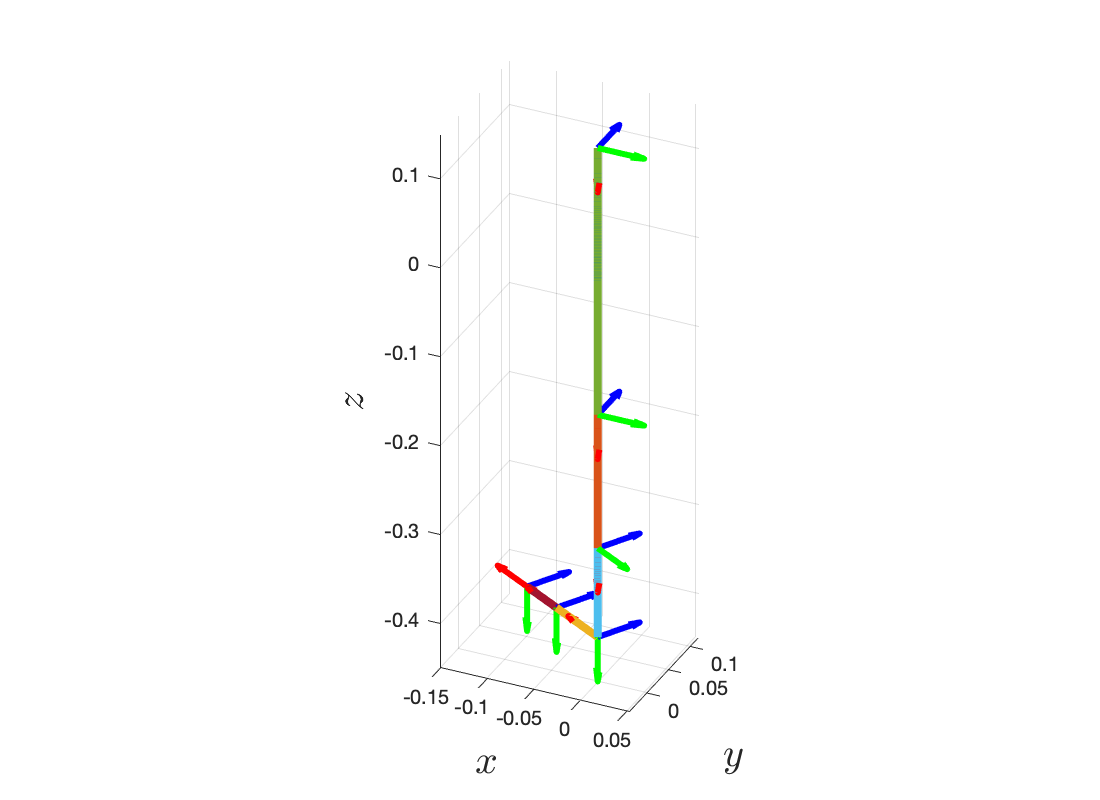


% draw figure
figure
hold on
grid on
drawLine3D(o1,o2);
drawCoordinate3DScale(R2,o2, 0.05);
drawLine3D(o2,o3);
drawCoordinate3DScale(R3,o3, 0.05);
drawLine3D(o3,o4);
drawCoordinate3DScale(R4,o4, 0.05);
drawLine3D(o4,o5);
drawCoordinate3DScale(R5,o5, 0.05);
drawLine3D(o5,o6);
drawCoordinate3DScale(R6,o6, 0.05);
drawLine3D(o6,oee);
drawCoordinate3DScale(Ree,oee, 0.05);
% R = eye(3);
xlabel('$x$','interpreter','latex','fontsize',20)
ylabel('$y$','interpreter','latex','fontsize',20)
zlabel('$z$','interpreter','latex','fontsize',20)
axis equal
fig=gcf;
fig.Position(3:4)=[550,400];


view(25,30)

(b) q = (0 , 120 , 0 , 60, 90, 0 )

[o1,R1, o2,R2, o3,R3, o4,R4, o5,R5, o6, R6, oee, Ree] = arm(0,degtorad(120),0,degtorad(60),degtorad(90),0)

$$o1 = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

$$R1 = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 1 \end{array}\right)$$

$$o2 = \left(\begin{array}{c} 0\\ 0\\ \frac{3}{20} \end{array}\right)$$

$$R2 = \left(\begin{array}{ccc} -\frac{1}{2} & 0 & \frac{\sqrt{3}}{2}\\ 0 & 1 & 0\\ -\frac{\sqrt{3}}{2} & 0 & -\frac{1}{2} \end{array}\right)$$

$$o3 = \left(\begin{array}{c} -\frac{3}{20}\\ 0\\ \frac{3}{20}-\frac{3\,\sqrt{3}}{20} \end{array}\right)$$

$$R3 = \left(\begin{array}{ccc} -\frac{1}{2} & 0 & \frac{\sqrt{3}}{2}\\ 0 & 1 & 0\\ -\frac{\sqrt{3}}{2} & 0 & -\frac{1}{2} \end{array}\right)$$

$$o4 = \left(\begin{array}{c} -\frac{9}{40}\\ 0\\ \frac{3}{20}-\frac{9\,\sqrt{3}}{40} \end{array}\right)$$

$$R4 = \left(\begin{array}{ccc} -\frac{1}{2} & \frac{3}{4} & \frac{\sqrt{3}}{4}\\ 0 & \frac{1}{2} & -\frac{\sqrt{3}}{2}\\ -\frac{\sqrt{3}}{2} & -\frac{\sqrt{3}}{4} & -\frac{1}{4} \end{array}\right)$$

$$o5 = \left(\begin{array}{c} -\frac{11}{40}\\ 0\\ \frac{3}{20}-\frac{11\,\sqrt{3}}{40} \end{array}\right)$$

$$R5 = \left(\begin{array}{ccc} -\frac{\sqrt{3}}{4} & \frac{3}{4} & -\frac{1}{2}\\ \frac{\sqrt{3}}{2} & \frac{1}{2} & 0\\ \frac{1}{4} & -\frac{\sqrt{3}}{4} & -\frac{\sqrt{3}}{2} \end{array}\right)$$

$$o6 = \left(\begin{array}{c} -\frac{7\,\sqrt{3}}{400}-\frac{11}{40}\\ \frac{7\,\sqrt{3}}{200}\\ \frac{67}{400}-\frac{11\,\sqrt{3}}{40} \end{array}\right)$$

$$R6 = \left(\begin{array}{ccc} -\frac{\sqrt{3}}{4} & \frac{3}{4} & -\frac{1}{2}\\ \frac{\sqrt{3}}{2} & \frac{1}{2} & 0\\ \frac{1}{4} & -\frac{\sqrt{3}}{4} & -\frac{\sqrt{3}}{2} \end{array}\right)$$

$$oee = \left(\begin{array}{c} -\frac{3\,\sqrt{3}}{100}-\frac{11}{40}\\ \frac{3\,\sqrt{3}}{50}\\ \frac{9}{50}-\frac{11\,\sqrt{3}}{40} \end{array}\right)$$

$$Ree = \left(\begin{array}{ccc} -\frac{\sqrt{3}}{4} & \frac{3}{4} & -\frac{1}{2}\\ \frac{\sqrt{3}}{2} & \frac{1}{2} & 0\\ \frac{1}{4} & -\frac{\sqrt{3}}{4} & -\frac{\sqrt{3}}{2} \end{array}\right)$$

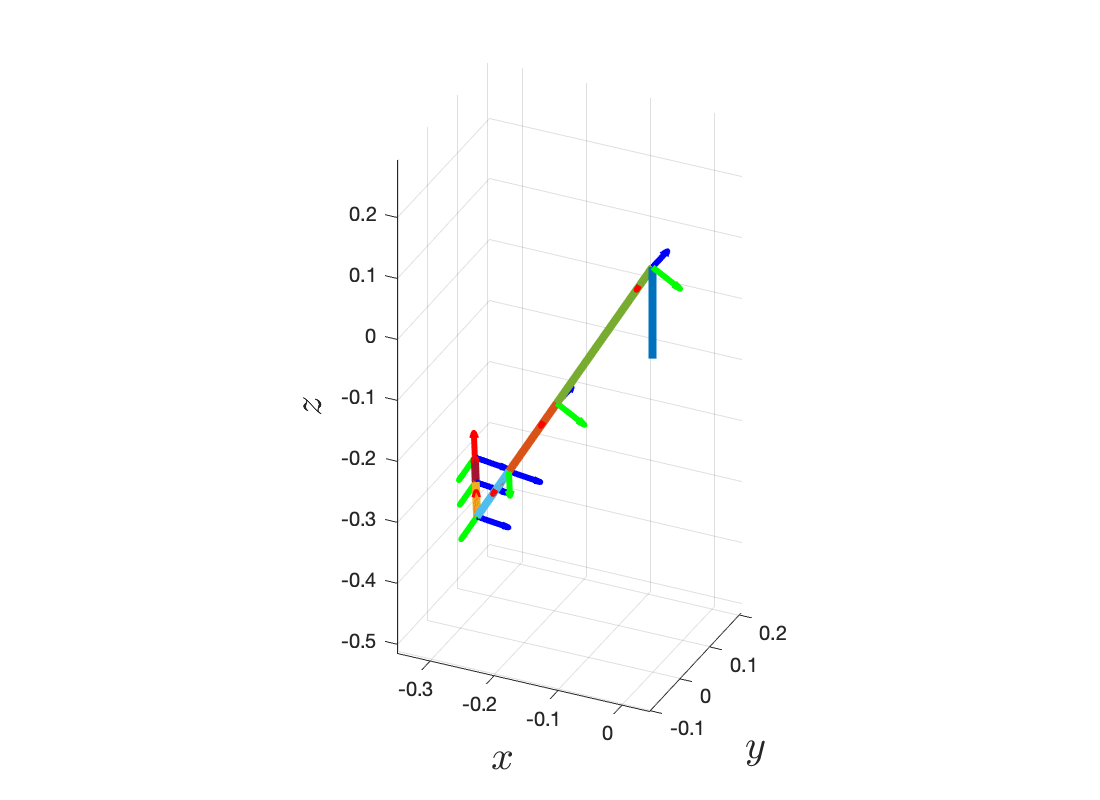


% draw figure
figure
hold on
grid on
drawLine3D(o1,o2);
drawCoordinate3DScale(R2,o2, 0.05);
drawLine3D(o2,o3);
drawCoordinate3DScale(R3,o3, 0.05);
drawLine3D(o3,o4);
drawCoordinate3DScale(R4,o4, 0.05);
drawLine3D(o4,o5);
drawCoordinate3DScale(R5,o5, 0.05);
drawLine3D(o5,o6);
drawCoordinate3DScale(R6,o6, 0.05);
drawLine3D(o6,oee);
drawCoordinate3DScale(Ree,oee, 0.05);
% R = eye(3);
xlabel('$x$','interpreter','latex','fontsize',20)
ylabel('$y$','interpreter','latex','fontsize',20)
zlabel('$z$','interpreter','latex','fontsize',20)
axis equal
fig=gcf;
fig.Position(3:4)=[550,400];


view(25,30)

2. Find the corresponding end-effector (i.e EE) SE(3) for the following two configurations

(a) q = (0, 90, 90, 30, 90, 0)

[o1,R1, o2,R2, o3,R3, o4,R4, o5,R5, o6, R6, oee, Ree] = arm(0,degtorad(90),degtorad(90),degtorad(30),degtorad(90),0)

$$o1 = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

$$R1 = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 1 \end{array}\right)$$

$$o2 = \left(\begin{array}{c} 0\\ 0\\ \frac{3}{20} \end{array}\right)$$

$$R2 = \left(\begin{array}{ccc} 0 & 0 & 1\\ 0 & 1 & 0\\ -1 & 0 & 0 \end{array}\right)$$

$$o3 = \left(\begin{array}{c} 0\\ 0\\ -\frac{3}{20} \end{array}\right)$$

$$R3 = \left(\begin{array}{ccc} -1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & -1 \end{array}\right)$$

$$o4 = \left(\begin{array}{c} -\frac{3}{20}\\ 0\\ -\frac{3}{20} \end{array}\right)$$

$$R4 = \left(\begin{array}{ccc} -1 & 0 & 0\\ 0 & \frac{\sqrt{3}}{2} & -\frac{1}{2}\\ 0 & -\frac{1}{2} & -\frac{\sqrt{3}}{2} \end{array}\right)$$

$$o5 = \left(\begin{array}{c} -\frac{1}{4}\\ 0\\ -\frac{3}{20} \end{array}\right)$$

$$R5 = \left(\begin{array}{ccc} 0 & 0 & -1\\ \frac{1}{2} & \frac{\sqrt{3}}{2} & 0\\ \frac{\sqrt{3}}{2} & -\frac{1}{2} & 0 \end{array}\right)$$

$$o6 = \left(\begin{array}{c} -\frac{1}{4}\\ \frac{7}{200}\\ \frac{7\,\sqrt{3}}{200}-\frac{3}{20} \end{array}\right)$$

$$R6 = \left(\begin{array}{ccc} 0 & 0 & -1\\ \frac{1}{2} & \frac{\sqrt{3}}{2} & 0\\ \frac{\sqrt{3}}{2} & -\frac{1}{2} & 0 \end{array}\right)$$

$$oee = \left(\begin{array}{c} -\frac{1}{4}\\ \frac{3}{50}\\ \frac{3\,\sqrt{3}}{50}-\frac{3}{20} \end{array}\right)$$

$$Ree = \left(\begin{array}{ccc} 0 & 0 & -1\\ \frac{1}{2} & \frac{\sqrt{3}}{2} & 0\\ \frac{\sqrt{3}}{2} & -\frac{1}{2} & 0 \end{array}\right)$$


digits(8)

Tee = [Ree, oee;
    0 0 0 1];
disp(vpa(Tee))

$$\left(\begin{array}{cccc} 0 & 0 & -1.0 & -0.25\\ 0.5 & 0.8660254 & 0 & 0.06\\ 0.8660254 & -0.5 & 0 & -0.046076952\\ 0 & 0 & 0 & 1.0 \end{array}\right)$$

(b) q = (0, 60, 45, 60, 90, 0)

[o1,R1, o2,R2, o3,R3, o4,R4, o5,R5, o6, R6, oee, Ree] = arm(0,degtorad(60),degtorad(45),degtorad(60),degtorad(90),0)

$$o1 = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

$$R1 = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 1 \end{array}\right)$$

$$o2 = \left(\begin{array}{c} 0\\ 0\\ \frac{3}{20} \end{array}\right)$$

$$R2 = \left(\begin{array}{ccc} \frac{1}{2} & 0 & \frac{\sqrt{3}}{2}\\ 0 & 1 & 0\\ -\frac{\sqrt{3}}{2} & 0 & \frac{1}{2} \end{array}\right)$$

$$o3 = \left(\begin{array}{c} \frac{3}{20}\\ 0\\ \frac{3}{20}-\frac{3\,\sqrt{3}}{20} \end{array}\right)$$

$$R3 = \left(\begin{array}{ccc} \frac{\sqrt{2}}{4}-\frac{\sqrt{2}\,\sqrt{3}}{4} & 0 & \frac{\sqrt{2}\,\sqrt{3}}{4}+\frac{\sqrt{2}}{4}\\ 0 & 1 & 0\\ -\frac{\sqrt{2}\,\sqrt{3}}{4}-\frac{\sqrt{2}}{4} & 0 & \frac{\sqrt{2}}{4}-\frac{\sqrt{2}\,\sqrt{3}}{4} \end{array}\right)$$

$$o4 = \left(\begin{array}{c} \frac{3\,\sqrt{2}}{80}-\frac{3\,\sqrt{2}\,\sqrt{3}}{80}+\frac{3}{20}\\ 0\\ \frac{3}{20}-\frac{3\,\sqrt{2}}{80}-\frac{3\,\sqrt{3}}{20}-\frac{3\,\sqrt{2}\,\sqrt{3}}{80} \end{array}\right)$$

$$R4 = \begin{array}{l} \left(\begin{array}{ccc} \frac{\sqrt{2}}{4}-\sigma_{1} & \frac{\sqrt{3}\,\left(\sigma_{1}+\frac{\sqrt{2}}{4}\right)}{2} & \frac{\sqrt{2}\,\sqrt{3}}{8}+\frac{\sqrt{2}}{8}\\ 0 & \frac{1}{2} & -\frac{\sqrt{3}}{2}\\ -\sigma_{1}-\frac{\sqrt{2}}{4} & -\frac{\sqrt{3}\,\left(\sigma_{1}-\frac{\sqrt{2}}{4}\right)}{2} & \frac{\sqrt{2}}{8}-\frac{\sqrt{2}\,\sqrt{3}}{8} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\sqrt{2}\,\sqrt{3}}{4} \end{array}$$

$$o5 = \left(\begin{array}{c} \frac{\sqrt{2}}{16}-\frac{\sqrt{2}\,\sqrt{3}}{16}+\frac{3}{20}\\ 0\\ \frac{3}{20}-\frac{\sqrt{2}}{16}-\frac{3\,\sqrt{3}}{20}-\frac{\sqrt{2}\,\sqrt{3}}{16} \end{array}\right)$$

$$R5 = \begin{array}{l} \left(\begin{array}{ccc} -\frac{\sqrt{2}\,\sqrt{3}}{8}-\frac{\sqrt{2}}{8} & \frac{\sqrt{3}\,\left(\sigma_{1}+\frac{\sqrt{2}}{4}\right)}{2} & \frac{\sqrt{2}}{4}-\sigma_{1}\\ \frac{\sqrt{3}}{2} & \frac{1}{2} & 0\\ \frac{\sqrt{2}\,\sqrt{3}}{8}-\frac{\sqrt{2}}{8} & -\frac{\sqrt{3}\,\left(\sigma_{1}-\frac{\sqrt{2}}{4}\right)}{2} & -\sigma_{1}-\frac{\sqrt{2}}{4} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\sqrt{2}\,\sqrt{3}}{4} \end{array}$$

$$o6 = \left(\begin{array}{c} \frac{43\,\sqrt{2}}{800}-\frac{57\,\sqrt{2}\,\sqrt{3}}{800}+\frac{3}{20}\\ \frac{7\,\sqrt{3}}{200}\\ \frac{3}{20}-\frac{57\,\sqrt{2}}{800}-\frac{3\,\sqrt{3}}{20}-\frac{43\,\sqrt{2}\,\sqrt{3}}{800} \end{array}\right)$$

$$R6 = \begin{array}{l} \left(\begin{array}{ccc} -\frac{\sqrt{2}\,\sqrt{3}}{8}-\frac{\sqrt{2}}{8} & \frac{\sqrt{3}\,\left(\sigma_{1}+\frac{\sqrt{2}}{4}\right)}{2} & \frac{\sqrt{2}}{4}-\sigma_{1}\\ \frac{\sqrt{3}}{2} & \frac{1}{2} & 0\\ \frac{\sqrt{2}\,\sqrt{3}}{8}-\frac{\sqrt{2}}{8} & -\frac{\sqrt{3}\,\left(\sigma_{1}-\frac{\sqrt{2}}{4}\right)}{2} & -\sigma_{1}-\frac{\sqrt{2}}{4} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\sqrt{2}\,\sqrt{3}}{4} \end{array}$$

$$oee = \left(\begin{array}{c} \frac{19\,\sqrt{2}}{400}-\frac{31\,\sqrt{2}\,\sqrt{3}}{400}+\frac{3}{20}\\ \frac{3\,\sqrt{3}}{50}\\ \frac{3}{20}-\frac{31\,\sqrt{2}}{400}-\frac{3\,\sqrt{3}}{20}-\frac{19\,\sqrt{2}\,\sqrt{3}}{400} \end{array}\right)$$

$$Ree = \begin{array}{l} \left(\begin{array}{ccc} -\frac{\sqrt{2}\,\sqrt{3}}{8}-\frac{\sqrt{2}}{8} & \frac{\sqrt{3}\,\left(\sigma_{1}+\frac{\sqrt{2}}{4}\right)}{2} & \frac{\sqrt{2}}{4}-\sigma_{1}\\ \frac{\sqrt{3}}{2} & \frac{1}{2} & 0\\ \frac{\sqrt{2}\,\sqrt{3}}{8}-\frac{\sqrt{2}}{8} & -\frac{\sqrt{3}\,\left(\sigma_{1}-\frac{\sqrt{2}}{4}\right)}{2} & -\sigma_{1}-\frac{\sqrt{2}}{4} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\sqrt{2}\,\sqrt{3}}{4} \end{array}$$


Tee = [Ree, oee;
    0 0 0 1];
disp(vpa(Tee))

$$\left(\begin{array}{cccc} -0.48296291 & 0.8365163 & -0.25881905 & 0.027339689\\ 0.8660254 & 0.5 & 0 & 0.10392305\\ 0.12940952 & -0.22414387 & -0.96592583 & -0.33575994\\ 0 & 0 & 0 & 1.0 \end{array}\right)$$

function [o1,R1, o2,R2, o3,R3, o4,R4, o5,R5, o6, R6, oee, Ree] = arm(th1,th2,th3,th4,th5,th6)
    syms theta
    Rx = [1, 0, 0;
        0, cos(theta), -sin(theta);
        0 sin(theta), cos(theta);
        ];
    Ry = [cos(theta), 0, sin(theta);
        0, 1, 0;
        -sin(theta), 0, cos(theta);
        ];
    Rz = [cos(theta), -sin(theta), 0;
        sin(theta), cos(theta), 0;
        0 0, 1;
        ];
    syms p1 p2 p3
    P = [p1;  p2; p3];
    Tx =[Rx, P;
        0 0 0 1];
    Ty =[Ry, P;
        0 0 0 1];
    Tz =[Rz, P;
        0 0 0 1];
    T01 = subs(Tz,{theta,p1, p2, p3},{th1,0,0,0});
    T12 = subs(Ty,{theta,p1, p2, p3},{th2,0,0,0.15});
    T23 = subs(Ty,{theta,p1, p2, p3},{th3,0.3,0,0});
    T34 = subs(Tx,{theta,p1, p2, p3},{th4,0.15,0,0});
    T45 = subs(Ty,{theta,p1, p2, p3},{th5,0.1,0,0});
    T56 = subs(Tx,{theta,p1, p2, p3},{th6,0.07,0,0});
    T6EE = subs(Tx,{theta,p1, p2, p3},{0,0.05,0,0});
    
    [R1, o1] = Textract(T01);
    
    T02 = Tmul(T01, T12);
    [R2, o2] = Textract(T02);
    
    T03 = Tmul(T02, T23);
    [R3, o3] = Textract(T03);
    
    T04 = Tmul(T03, T34);
    [R4, o4] = Textract(T04);
    
    T05 = Tmul(T04, T45);
    [R5, o5] = Textract(T05);
    
    T06 = Tmul(T05, T56);
    [R6, o6] = Textract(T06);
    
    T0EE = Tmul(T06, T6EE);
    oee = T0EE(1:3,4);    
    Ree = T0EE(1:3,1:3);
end

function Tres = Tmul(T1, T2)
    Tres = T1 * T2;
end

function Tres = Tinv(T)
    R = T(1:3,1:3);
    p = T(1:3,4);
    
    Tres =[R.', -R.' * p;
    0 0 0 1];
end

function [R,p] = Textract(T)
    R = T(1:3,1:3);
    p = T(1:3,4);
end